# Try8 version1 ultime（不规则，高斯迭代，for循环，相容误差，flux）

基于版本try4

有加热器的地方有flux，没有加热器的地方flux为零

## Paramètre


x=10;   %longueur en x
y=5;   %longueur en y
h=.1;  %pas
m=0:h:x;
n=0:h:y;
flux_chaleur=-10000; % -phi/k
T=zeros(length(n),length(m));
length(T);
Echelon=ones(length(n),length(m));

## Condition frontière

T(1,:)=10;
T(:,1)=10;
T(length(n),:)=10;
T(:,length(m))=10;
T(30:40,1)=100;
T1=T;
% for i=1:20
%     for j=75:101
%         Echelon(i,j)=0;
%     end
% end
Echelon(1:20,75:101)=0

Echelon =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

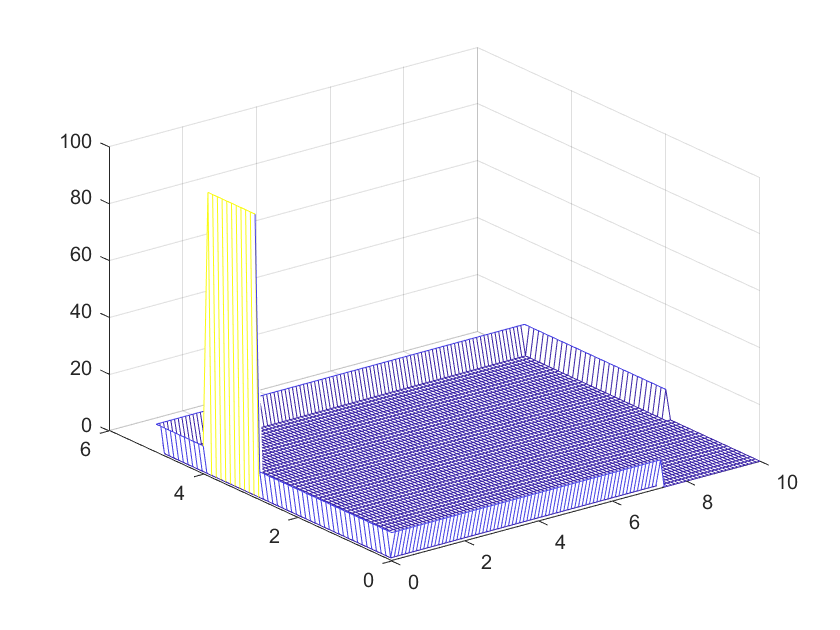

T=T.*Echelon;
[xq,yq] = meshgrid(m, n);
mesh(xq,yq,T)

% M=moviein(length(n)-2);

## i dislike for

accuracy=.000000001; count=0;
flag=zeros(length(n),length(m));
% error=zeros(length(n),length(m));
num=(length(n)-2)*(length(m)-2);
while count<=num
    for i=2:length(n)-1     %indice ligne
        for j=2:length(m)-1 %indice colonne
            if flag(i,j)==0
                temp_float=T(i,j);
                if((30<=i)&&(i<=40)&&(j==2))
                % -----N S W E -------%
                T(i,j)=(T(i-1,j) ...    %North
                +T(i+1,j) ...       %South
                +T(i,j-1) ...       %West
                +T(i,j+1))/4 ...    %East
                -(h^2*flux_chaleur)/4  ;       %complément si laplacien non nul 
                
                % -----/ N S W E -------%
                % -----N S W E -------%
                else
                T(i,j)=(T(i-1,j) ...    %North
                +T(i+1,j) ...       %South
                +T(i,j-1) ...       %West
                +T(i,j+1))/4;   %East
                % -----/ N S W E -------%
                end
                cur_err=(T(i,j)-temp_float)/T(i,j);
                T=T.*Echelon;
                %T=T1;
                
%                 M(i,j)=getframe(gcf);
            end
            if abs(cur_err)<=accuracy
                %error(i,j)=cur_err;
                 flag(i,j)=1;
                count=count+1;
            end
        end
    end    
end
count

count = 4877

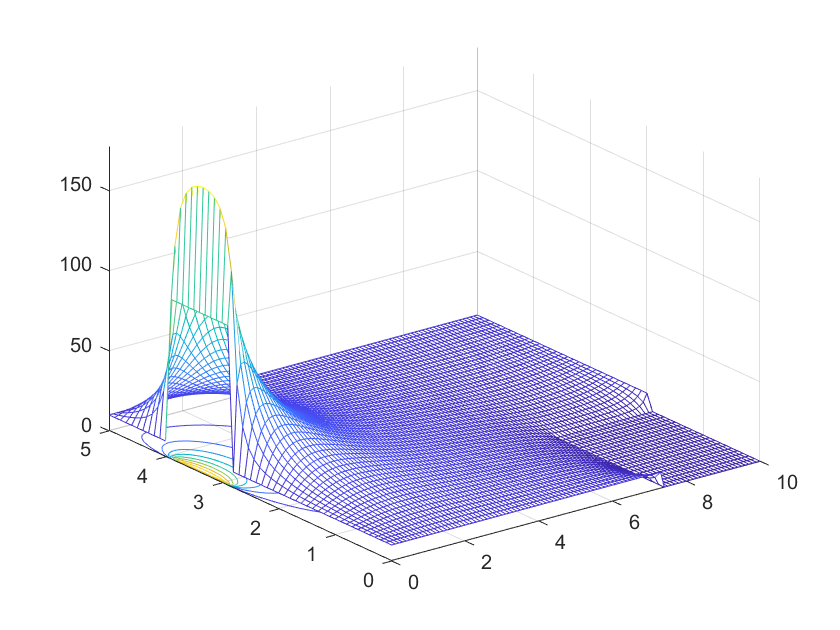

% movie(M)

% while max(max(e))>=0.1
%     for i=2:length(n)-1     %indice ligne
%         for j=2:length(m)-1 %indice colonne
%             T(i,j)=(T(i-1,j) ...    %North
%                 +T(i+1,j) ...       %South
%                 +T(i,j-1) ...       %West
%                 +T(i,j+1))/4 ...    %East
%                 -(h^2*.2)/4  ;       %complément si laplacien non nul
%             count=count--1;
%             e=(T-temp)/T;
%         end
%     end
% end
meshc(xq,yq,T)

下列代码长时间运行后也没有结果

e=1; count=0;

while max(max(e))>=0.1

    for i=2:length(n)-1     %indice ligne

        for j=2:length(m)-1 %indice colonne

            T(i,j)=(T(i-1,j) ...    %North

                +T(i+1,j) ...       %South

                +T(i,j-1) ...       %West

                +T(i,j+1))/4 ...    %East

                -(h^2*.2)/4  ;       %complément si laplacien non nul

            count=count--1;

            e=(T-temp)/T;

        end

    end

end

在使用相容误差的代码中，第一版本一直在运行无法得出结果，原因：

变量名不一致，我用了temp和temp_float

## boucle for version 2

accuracy=.1; count=0;

flag=zeros(length(n),length(m));

% error=zeros(length(n),length(m));

num=(length(n)-2)*(length(m)-2);

while count<num

    for i=2:length(n)-1     %indice ligne

        for j=2:length(m)-1 %indice colonne

            if flag(i,j)==0

                temp_float=T(i,j);

                % -----N S W E -------%

                T(i,j)=(T(i-1,j) ...    %North

                +T(i+1,j) ...       %South

                +T(i,j-1) ...       %West

                +T(i,j+1))/4 ...    %East

                -(h^2*.2)/4  ;       %complément si laplacien non nul  

                % -----/ N S W E -------%

                cur_err=(T(i,j)-temp_float)/T(i,j);

            end

            if abs(cur_err)<=accuracy

                %error(i,j)=cur_err;

                flag(i,j)=1;

                count=count+1;

            end

        end

    end    

end